## Set the AWS default region. Code won't run without this.

setenv('AWS_DEFAULT_REGION','us-west-1')

## Load the FileSets

load('s3://childmind/matlab/FileSet_train.mat','-mat','fs_train');
load('s3://childmind/matlab/FileSet_val.mat','-mat','fs_val');

## Create the datastore

train_sds = signalDatastore(fs_train);
val_sds = signalDatastore(fs_val);

## Custom reader function

No need for custom reader function when using signalDatastore

## Preview the first sample of the datastore

sample = preview(train_sds);
fprintf('Sample size = %d, %d \n', size(sample));

Sample size = 24, 256 


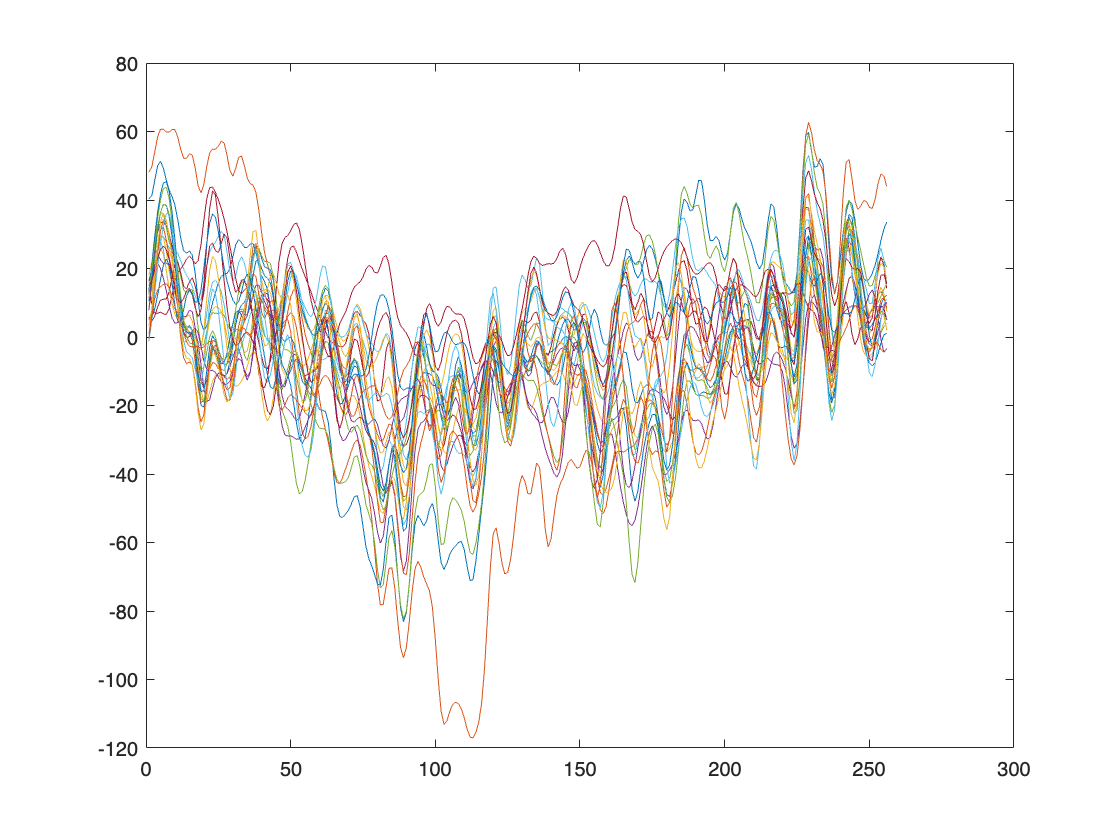

plot(sample');

## Assign labels

load("train_labels.mat")
load("val_labels.mat")

ds = arrayDatastore(train_label_info,'OutputType','same');
train_labelsDatastore = transform(ds, @(x) {categorical(x{3},[0,1])});

ds = arrayDatastore(val_label_info,'OutputType','same');
val_labelsDatastore = transform(ds, @(x) {categorical(x{3},[0,1])});

## Combine signals and labels

trainDs = combine(train_sds,train_labelsDatastore);
valDs = combine(val_sds,val_labelsDatastore);

prevData = preview(trainDs)

prevData = 1×2 cell array
    {24×256 single}    {[0]}


## Define the network layers to be trained

channels = [1, 24]; %range of channels 
num_samples = 256; %num of samples
data_size = [channels(2)-channels(1)+1 num_samples 1]; 

num_labels = numel(categories(prevData{2}));

layers = [
    imageInputLayer(data_size,"Name","imageinput","Normalization","none")
    convolution2dLayer([3 3],16,"Name","conv1","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu1_1")
    convolution2dLayer([3 3],16,"Name","conv2","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu1_2")
    maxPooling2dLayer([2 2],"Name","pool1","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],32,"Name","conv3","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_1")
    convolution2dLayer([3 3],32,"Name","conv4","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_2")
    maxPooling2dLayer([2 2],"Name","pool2","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],64,"Name","conv5","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_1")
    convolution2dLayer([3 3],64,"Name","conv6","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_2")
    convolution2dLayer([3 3],64,"Name","conv7","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_3")
    maxPooling2dLayer([2 2],"Name","pool3","Padding","same","Stride",[2 2])
    fullyConnectedLayer(1024,"Name","fc1","WeightL2Factor",0)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop1")
    fullyConnectedLayer(1024,"Name","fc2","WeightL2Factor",0)
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop2")
    fullyConnectedLayer(num_labels,"Name","fc3","WeightL2Factor",0)
    softmaxLayer("Name","prob")
    classificationLayer("Name","classoutput")];

## Training the network

Define training settings. There are several [training options](https://in.mathworks.com/help/deeplearning/ref/trainingoptions.html) available. Try different options to improve performance.

options = trainingOptions('adam', ...
    'InitialLearnRate',0.0005, ...
    'SquaredGradientDecayFactor',0.99, ...
    'MaxEpochs',2, ...
    'MiniBatchSize',70, ...
    'ValidationData',valDs);

Train the network

eeg_net = trainNetwork(trainDs,layers,options);

## Alternatively:  load all the data to local memory and then training will be faster

allData = readall(trainDs,"UseParallel",true); % trainDs is a combined datastore that reads from the AWS signals and from the labels arrayDatastore

This call reads the entire training data in parallel using all your machine processors. It still takes a long time but now training with this data will be much faster and you can actually increase the number of training epochs without paying a high price. 

eeg_net = trainNetwork(allData,layers,options);